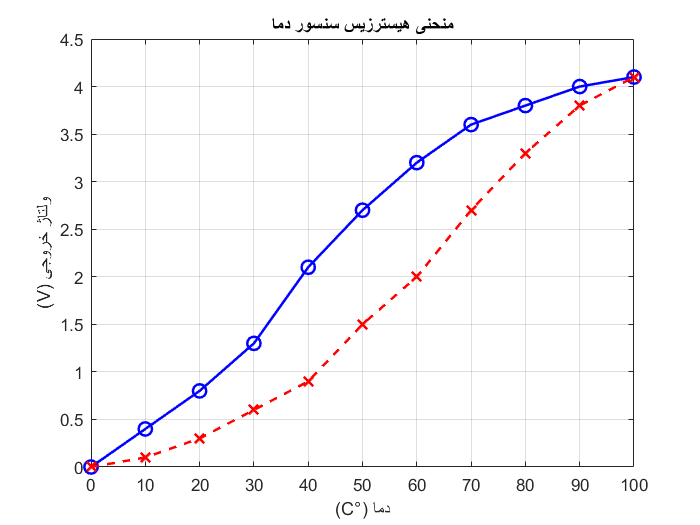

Temperature = [0,10,20,30,40,50,60,70,80,90,100];
Voltage_Increasing = [0, 0.4, 0.8, 1.3, 2.1, 2.7, 3.2, 3.6, 3.8, 4, 4.1];
Voltage_Decreasing = [0,0.1,0.3,0.6,0.9,1.5,2,2.7,3.3,3.8,4.1];

figure;
plot(Temperature, Voltage_Increasing, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', 'حالت افزایش دما');
hold on;
plot(Temperature, Voltage_Decreasing, 'r--x', 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', 'حالت کاهش دما');
xlabel('دما (°C)');
ylabel('ولتاژ خروجی (V)');
title('منحنی هیسترزیس سنسور دما');
grid on;
hold off;


Hysteresis_Voltage = abs(Voltage_Decreasing - Voltage_Increasing);
FS = 4.1;
Max_Hysteresis_Voltage = max(Hysteresis_Voltage);
Max_Hysteresis_Percent = (Max_Hysteresis_Voltage / FS) * 100;

[~, idx] = max(Hysteresis_Voltage);
Max_Hysteresis_Temperature = Temperature(idx);

